% Dimensionamento do eixo de saida - redutor para transportadora redler
clear; clc; close all;
%% Dados
P = 5.5;          % cv
P = 5.5 * 1000   % W

P = 5500

OMEGA = 1750;   % rpm
a = 5.9;        % mm
b = 132.31;        % mm
c = 168;        % mm
p = 27.17;        % mm
q = 221.5;       % mm
s = 5.9;       % mm
dg = 180;
dg = 180/1000;
rg = 0.5*dg     % mm

rg = 0.0900

ds = 180; 
ds = 180/1000; % mm
rs = 0.5*ds     % mm

rs = 0.0900

PHIdeg = 20;    % deg
PHI = PHIdeg * (2 * pi / 360)   % rad

PHI = 0.3491


%% Solution
%
% 1
T = (P*30/(OMEGA * pi)) *1000    % Nmm

T = 3.0012e+04

%
% 2
RHO = 132,31;     

RHO = 132

Ft = T/rs   % N

Ft = 3.3347e+05

F1 = Ft / (1 - (1/RHO)) % N

F1 = 3.3601e+05

F2 = F1 - Ft    % N

F2 = 2.5456e+03

Fs = F1 + F2    % N

Fs = 3.3856e+05

%
% 3
Fgt = T / rg    % N

Fgt = 3.3347e+05

Fgr = Fgt * tan(PHI)    % N

Fgr = 1.2137e+05

%
% 4
% < FIGURE E10-1>
% < FIGURE E10-2>
R2x = (1/b)*(-Fgr*p - Fs*q)  % N

R2x = -5.9170e+05

R1x = -Fgr - R2x - Fs   % N

R1x = 1.3177e+05

R2y = (1/b)*(Fgt*p) % N

R2y = 6.8478e+04

R1y = Fgt - R2y     % N

R1y = 2.6499e+05

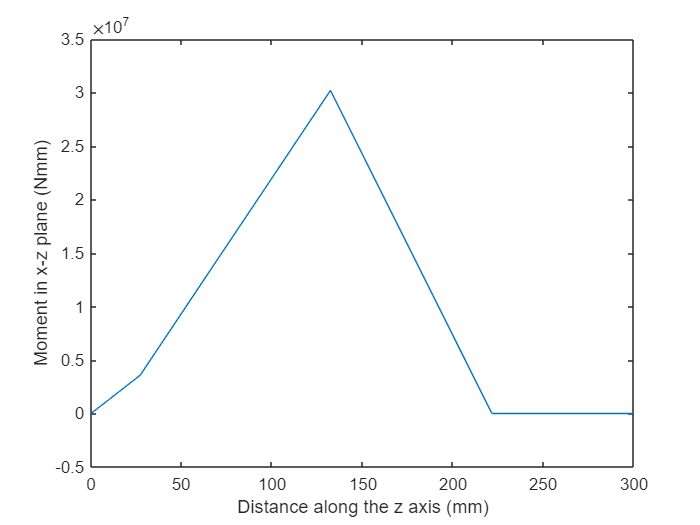

%
z = 0:0.2:300;    % mm
Vy = R1x .* (z>=0).*z.^0 + Fgr .* (z>=p) .*(z-p).^0 + R2x .* (z>=b) .*(z-b).^0 + Fs .* (z>=q) .*(z-q).^0;
My = R1x.*(z>=0).*(z-0).^1 + Fgr.*(z>=p).*(z-p).^1 + R2x.*(z>=b).*(z-b).^1 + Fs.*(z>=q).*(z-q).^1;


figure
plot(z,My)
xlabel('Distance along the z axis (mm)')
ylabel('Moment in x-z plane (Nmm)')

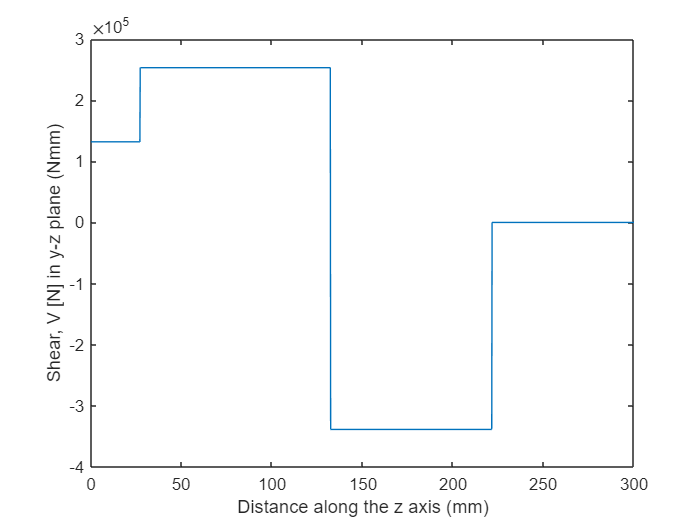


figure
plot(z,Vy)
xlabel('Distance along the z axis (mm)')
ylabel('Shear, V [N] in y-z plane (Nmm)')

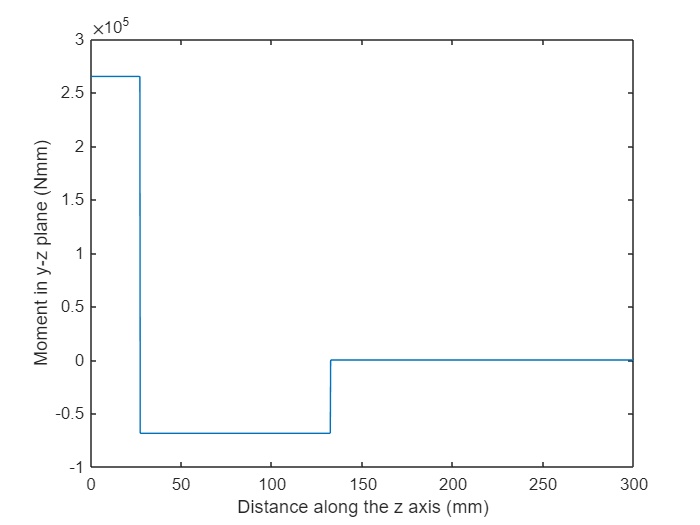


Vx = R1y .* (z>=0) .* z.^0 - Fgt .* (z>=p) .*  (z-p).^0 + R2y .* (z>=b) .* (z-b).^0;
Mx = R1y.*(z>=0).*(z-0).^1 - Fgt.*(z>=p).*(z-p).^1 + R2y.*(z>=b).*(z-b).^1;


figure
plot(z,Vx)
xlabel('Distance along the z axis (mm)')
ylabel('Moment in y-z plane (Nmm)')

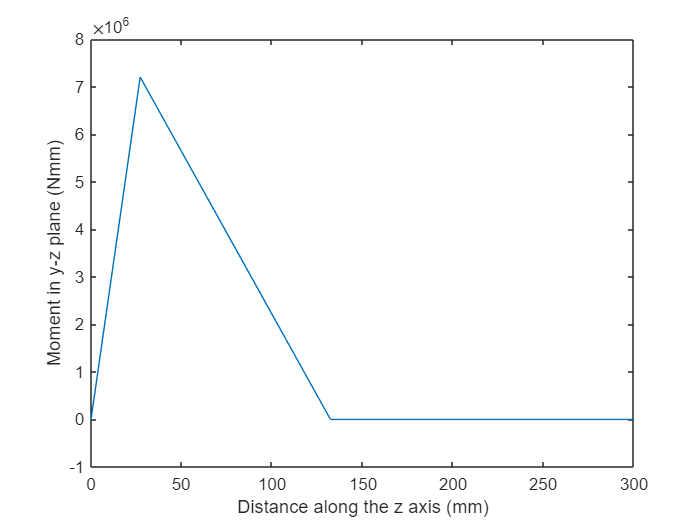


figure
plot(z,Mx)
xlabel('Distance along the z axis (mm)')
ylabel('Moment in y-z plane (Nmm)')

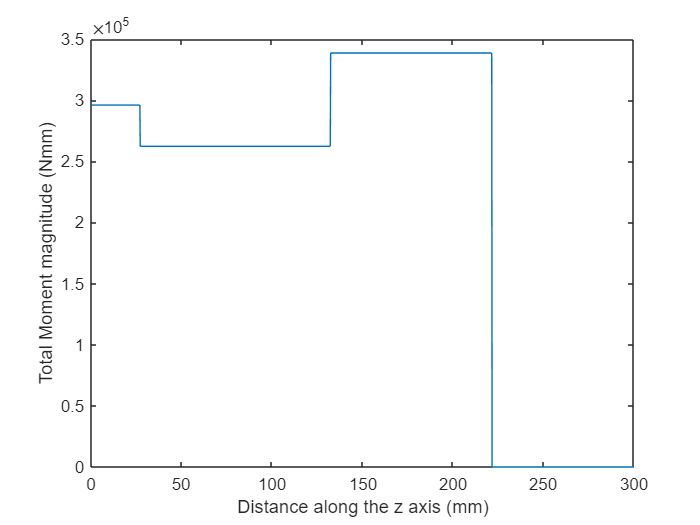



figure
V = (Vx.^2 + Vy.^2).^(1/2);
plot(z,V)
xlabel('Distance along the z axis (mm)')
ylabel('Total Moment magnitude (Nmm)')

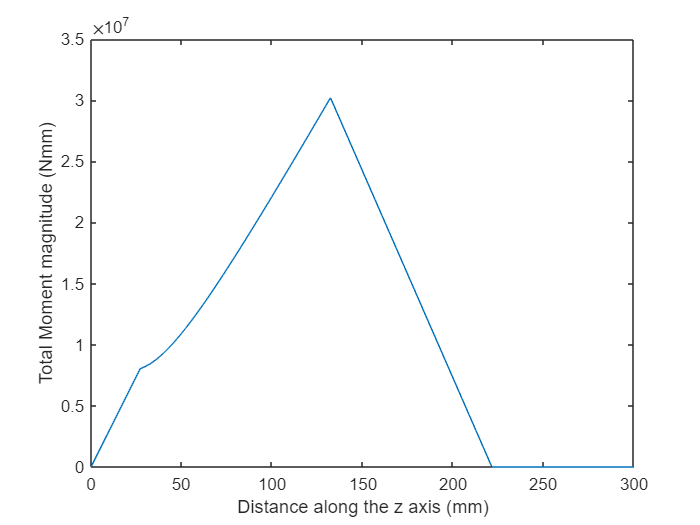


figure
M = (Mx.^2 + My.^2).^(1/2);
plot(z,M)
xlabel('Distance along the z axis (mm)')
ylabel('Total Moment magnitude (Nmm)')

%% Given
lAB = 132.31;  
lBC = 35;   % mm


dAB = 80; % mm
dBC = 60; % m

T = 16500;     % Nmm
G = 206e6;    % kPa
%
%% Solution
%
E=30e6; %Mpa
% 1
JAB = (pi/32) * dAB^4;   % mm^4
JBC = (pi/32) * dBC^4;   % mm^4


THETA = (T/G)*(lAB/JAB + lBC/JBC); % rad
THETAdeg = THETA * (360/(2*pi)); % deg
%
IAB = pi*dAB^4/64;
IBC = pi*dBC^4/64;


Iz = E*(IAB .* (z>=0) .* z.^0 + (IBC-IAB) .* (z>=a) .* (z-a).^0)

Iz = 1.0e+13 *

    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    6.0319    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085    1.9085


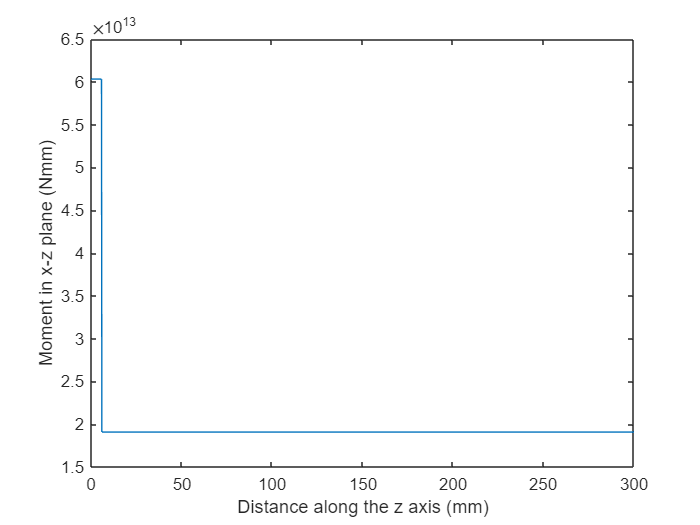



figure
plot(z,Iz)
xlabel('Distance along the z axis (mm)')
ylabel('Moment in x-z plane (Nmm)')

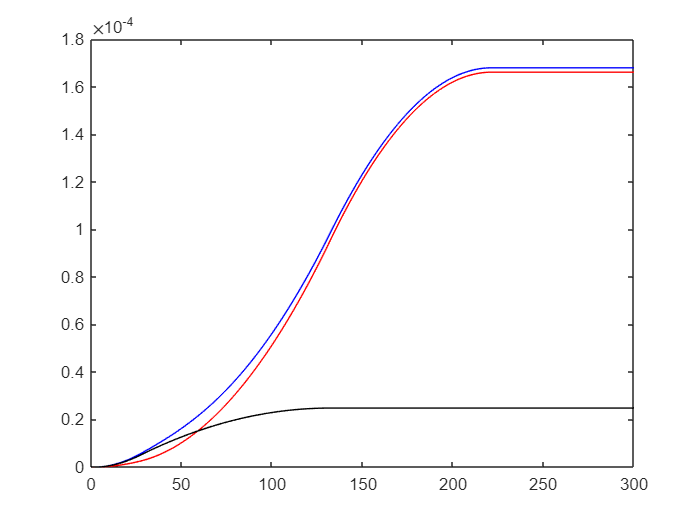



%% Solução Numérica
M_Ei_x = Mx./Iz;
M_Ei_y = My./Iz;

def_ang_x = modTrapInt(z,M_Ei_x);
def_x = modTrapInt(z,def_ang_x);

def_ang_y = modTrapInt(z,M_Ei_y);
def_y = modTrapInt(z,def_ang_y);

def_ang = (def_ang_x.^2+def_ang_y.^2).^(1/2);


%% plot
figure
plot(z, def_ang,'b');hold on
plot(z, def_ang_y, 'r');
plot(z, def_ang_x,'k');

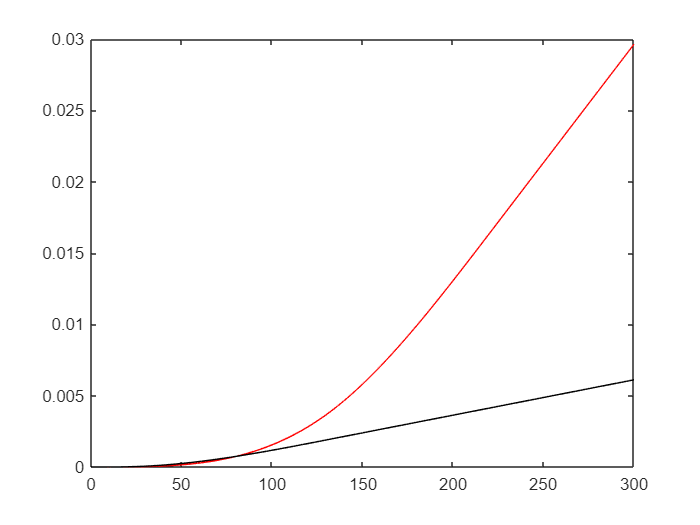


figure
plot(z, def_y, 'r');hold on
plot(z, def_x,'k');

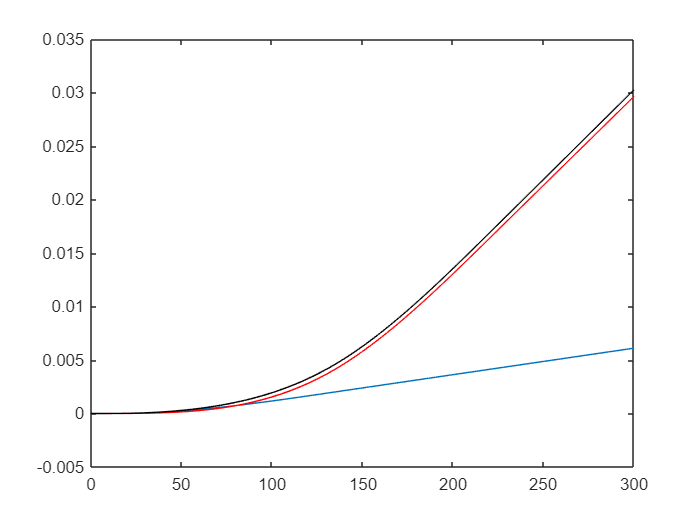


% Correção
C3x = atan(def_x(z==5)/5);
C3y = atan(def_y(z==5)/5);

def_tot_cor_x = def_x-C3x.*z;
def_tot_cor_y = def_y-C3y.*z;
def_tot_cor = (def_tot_cor_x.^2+def_tot_cor_y.^2).^(1/2);

def_ang_cor_x = def_ang_x-C3x;
def_ang_cor_y = def_ang_y-C3y;
def_ang_cor = (def_ang_cor_x.^2+def_ang_cor_y.^2).^(1/2);

figure
plot(z, def_tot_cor_x); hold on
plot(z, def_tot_cor_y, 'r'); hold on
plot(z, def_tot_cor, 'k'); hold on

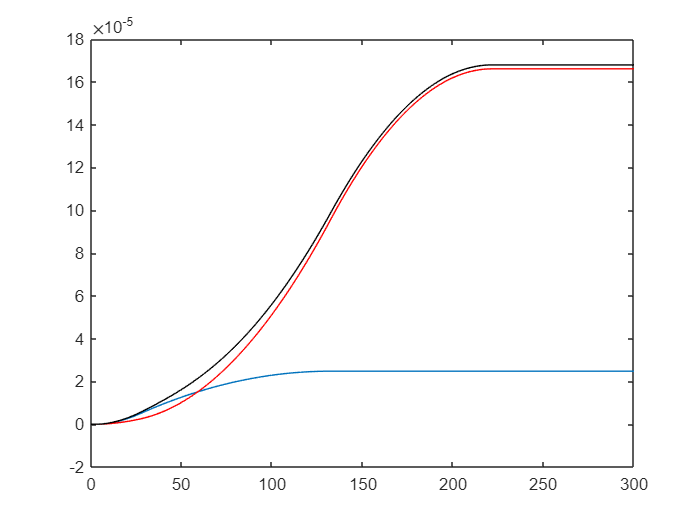


figure
plot(z, def_ang_cor_x); hold on
plot(z, def_ang_cor_y, 'r'); hold on
plot(z, def_ang_cor, 'k'); hold on